summary(Bloodsamplesdataset)

Variables:

    Glucose: 2351×1 double

        Values:

            Min       0.010994
            Median     0.35172
            Max        0.96846

    Cholesterol: 2351×1 double

        Values:

            Min       0.012139
            Median     0.39708
            Max        0.90503

    Hemoglobin: 2351×1 double

        Values:

            Min       0.0030213
            Median      0.60984
            Max         0.98331

    Platelets: 2351×1 double

        Values:

            Min       0.012594
            Median     0.53396
            Max        0.99939

    RedBloodCells: 2351×1 double

        Values:

            Min       0.044565
            Median     0.46743
            Max              1

    Insulin: 2351×1 double

        Values:

            Min       0.034129
            Median     0.44481
            Max        0.96678

    BMI: 2351×1 d

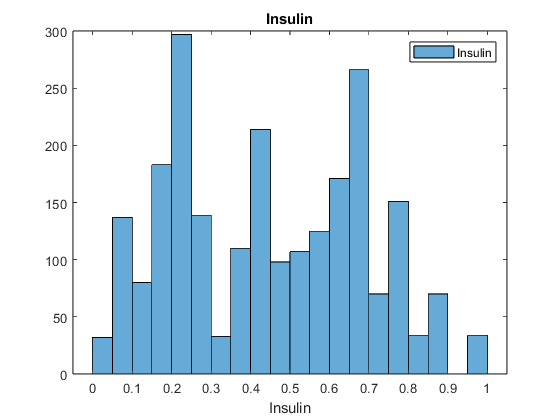

% Create histogram of Bloodsamplesdataset.Insulin
h2 = histogram(Bloodsamplesdataset.Insulin,'DisplayName','Insulin');

% Add xlabel, and title
xlabel('Insulin')
title('Insulin')
legend

spl = 0.2

spl = 0.2000

hpartition = cvpartition(length(Bloodsamplesdataset.Disease),'HoldOut',spl)

hpartition = Hold-out cross validation partition
   NumObservations: 2351
       NumTestSets: 1
         TrainSize: 1881
          TestSize: 470

idxTrain = training(hpartition);
trainData = Bloodsamplesdataset(idxTrain,:)

trainData = 1881×15 table
    Glucose     Cholesterol    Hemoglobin    Platelets    RedBloodCells    Insulin       BMI       SystolicBloodPressure    DiastolicBloodPressure    Triglycerides     HbA1c      LDLCholesterol    HDLCholesterol    CreactiveProtein    Disease 
    ________    ___________    __________    _________    _____________    ________    ________    _____________________    ______________________    _____________    ________    ______________    ______________    ________________    <s

idxTest= test(hpartition);
testData=Bloodsamplesdataset(idxTest,:)

testData = 470×15 table
    Glucose     Cholesterol    Hemoglobin    Platelets    RedBloodCells    Insulin       BMI       SystolicBloodPressure    DiastolicBloodPressure    Triglycerides     HbA1c      LDLCholesterol    HDLCholesterol    CreactiveProtein    Disease 
    ________    ___________    __________    _________    _____________    ________    ________    _____________________    ______________________    _____________    ________    ______________    ______________    ________________    

testAnswers = testData.Disease;
testData = removevars(testData,"Disease")

testData = 470×14 table
    Glucose     Cholesterol    Hemoglobin    Platelets    RedBloodCells    Insulin       BMI       SystolicBloodPressure    DiastolicBloodPressure    Triglycerides     HbA1c      LDLCholesterol    HDLCholesterol    CreactiveProtein
    ________    ___________    __________    _________    _____________    ________    ________    _____________________    ______________________    _____________    ________    ______________    ______________    ________________

      0.7396       0.6502       0.7

trainedModel

trainedModel = struct with fields:
           predictFcn: @(x)exportableModel.predictFcn(predictorExtractionFcn(x))
    RequiredVariables: {'BMI'  'Cholesterol'  'CreactiveProtein'  'DiastolicBloodPressure'  'Glucose'  'HDLCholesterol'  'HbA1c'  'Hemoglobin'  'Insulin'  'LDLCholesterol'  'Platelets'  'RedBloodCells'  'SystolicBloodPressure'  'Triglycerides'}
    ClassificationKNN: [1×1 ClassificationKNN]
                About: 'This struct is a trained model exported from Classification Learner R2021a.'
         HowToPredict: 'To make predictions on a new table, T, use: ↵  yfit = c.predictFcn(T) ↵replacing 'c' with the name of the variable that is this struct, e.g. 'trainedModel'. ↵ ↵The table, T, must contain the variables returned by: ↵  c.RequiredVariables ↵Variable formats (e.g. matrix/vector, datatype) must match the original training data. ↵Additional variables are ignored. ↵ ↵For more information, see 

model_ = trainedModel.ClassificationKNN

model_ =   ClassificationKNN
           PredictorNames: {'Glucose'  'Cholesterol'  'Hemoglobin'  'Platelets'  'RedBloodCells'  'Insulin'  'BMI'  'SystolicBloodPressure'  'DiastolicBloodPressure'  'Triglycerides'  'HbA1c'  'LDLCholesterol'  'HDLCholesterol'  'CreactiveProtein'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [Anemia    Diabetes    Healthy    Thalasse    Thromboc]
           ScoreTransform: 'none'
          NumObservations: 1881
                 Distance: 'euclidean'
             NumNeighbors: 10


  Properties, Methods


predicted_disease= trainedModel.predictFcn(testData)

predicted_disease = 470×1 categorical array
     Healthy 
     Thromboc 
     Diabetes 
     Diabetes 
     Healthy 
     Thalasse 
     Diabetes 
     Thalasse 
     Thalasse 
     Thalasse 
     Anemia 
     Thalasse 
     Diabetes 
     Thromboc 
     Anemia 
     Diabetes 
     Thalasse 
     Healthy 
     Healthy 
     Healthy 
     Diabetes 
     Thalasse 
     Thalasse 
     Diabetes 
     Anemia 
     Anemia 
     Thalasse 
     Healthy 
     Thalasse 
     Diabetes 


table(predicted_disease)

ans = 470×1 table
    predicted_disease
    _________________

        Healthy      
        Thromboc     
        Diabetes     
        Diabetes     
        Healthy      
        Thalasse     
        Diabetes     
        Thalasse     
        Thalasse     
        Thalasse     
        Anemia       
        Thalasse     
        Diabetes     
        Thromboc     
        Anemia       
        Diabetes     


%testErrors= testAnswers - predicted_disease
%testAvgError=sum(abs(testErrors)) ./length(testAnswers)
testLoss= loss(model_,testData,testAnswers)

testLoss = 0

trainLoss = loss(model_,trainData,trainData.Disease)

trainLoss = 0

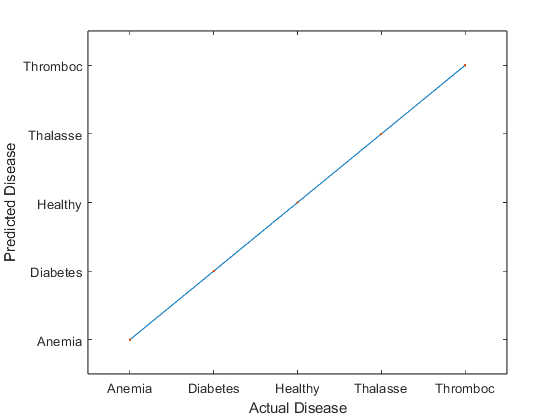

plot(testAnswers, testAnswers);
hold on
plot(testAnswers,predicted_disease,".");
hold off
xlabel('Actual Disease');
ylabel('Predicted Disease');

model_disease= trainedModel;
save model_disease.mat;

DiseaseID = (1:length(predicted_disease))';
testData = addvars(testData,DiseaseID,'Before', 'Glucose')

testData = 470×15 table
    DiseaseID    Glucose     Cholesterol    Hemoglobin    Platelets    RedBloodCells    Insulin       BMI       SystolicBloodPressure    DiastolicBloodPressure    Triglycerides     HbA1c      LDLCholesterol    HDLCholesterol    CreactiveProtein
    _________    ________    ___________    __________    _________    _____________    ________    ________    _____________________    ______________________    _____________    ________    ______________    ______________    __

testResults = table(testData.DiseaseID,predicted_disease, 'VariableNames',{'disease_id',...
    'predicted_disease'})

testResults = 470×2 table
    disease_id    predicted_disease
    __________    _________________

         1            Healthy      
         2            Thromboc     
         3            Diabetes     
         4            Diabetes     
         5            Healthy      
         6            Thalasse     
         7            Diabetes     
         8            Thalasse     
         9            Thalasse     
        10            Thalasse     
        11            Anemia       
        12            Thalasse     
        13            Diabetes     
        14            Thromboc     
        15            Anemia       
        16            Diabetes     


writetable(testResults,'testResults_disease.csv');